**Ideal Gas Heat Capacity**

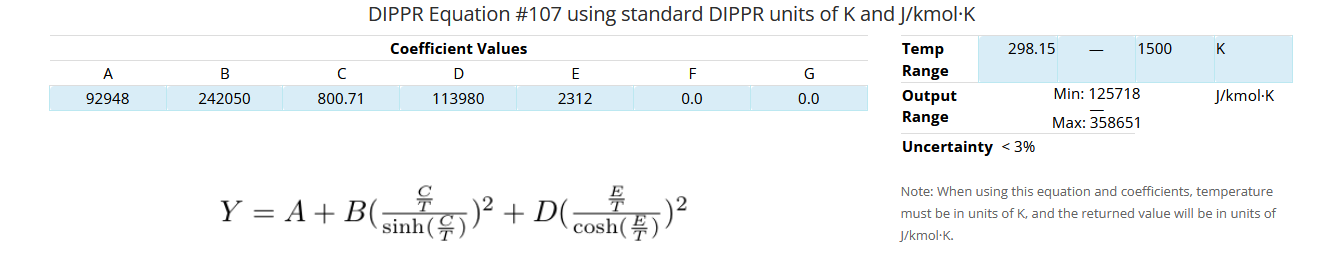

function Y = Cp_xil_vap(T_K)


TKmax = 1500;
TKmin = 298.15;

idxmax = find(T_K >= TKmax);
T_K(idxmax) = TKmax;

idxmin = find(T_K <= TKmin);
T_K(idxmin) = TKmin;

if ~isempty(idxmin)
    warning('A propriedade está a ser extrapolada para baixo!!')
elseif ~isempty(idxmax)
      warning('A propriedade está a ser extrapolada para cima!!')
end


A=299530;
B=1800.3;
C=-254600;
D=1437.8;
E=67360;
% F=0.0;
% G= 0.0;
 	 	 	
Y = A + B./T_K + C*T_K + D*T_K.^2 + E*T_K.^3; %  J/kmol·K
%Y = Y/1000/1000; % kJ/mol/K
end